# 1 Multi-class Classification

## **1.1 Dataset**

data.X 是 5000 * 400, 400 是 20 * 20 的手写图像的灰度矩阵向量化的结果

每一行代表了一个手写数字。

data.y 则是对应的 label，表明对应的图像代表的数字是几。

data = load('./ex3data1.mat');
data.X, data.y

## **1.2 Visualizing the data**

[m, n] = size(data.X);
% Randomly select 100 data points to display

ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

ans =     10
    10
    10
    10
    10
    10
    10
    10
    10
    10


rand_indices = randperm(m);
sel = X(rand_indices(1:100), :);
displayData(sel);

## 1.3 Vectorizing Logistic Regression

以下三个小节全部归到一个函数中去。

## **1.3.1 Vectorizing the cost function**

## **1.3.2 Vectorizing the gradient**

## **1.3.3 Vectorizing regularized logistic regression**

Testing lrCostFunction() with regularization

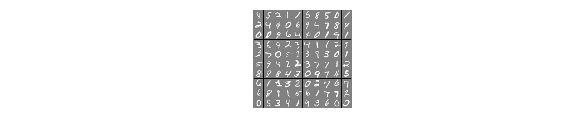

theta_t = [-2; -1; 1; 2];
X_t = [ones(5,1) reshape(1:15,5,3)/10];
y_t = ([1;0;1;0;1] >= 0.5);

lambda_t = 3;
[J grad] = lrCostFunction(theta_t, X_t, y_t, lambda_t);

Expected cost: 2.534819

fprintf('\nCost: %f\n', J);

Expected gradients:

    0.146561

    -0.548558

    0.724722

    1.398003

Gradients:

fprintf(' %f \n', grad);

## **1.4 One-vs-all Classification**

% figure, imshow(X(1, :))

Training One-vs-All Logistic Regression...

lambda = 0.1;
input_layer_size  = 400;  % 20x20 Input Images of Digits
num_labels = 10;          % 10 labels, from 1 to 10
                          % (note that we have mapped "0" to label 10)


Cost: 2.534819


% [all_theta] = oneVsAll(X, y, num_labels, lambda);
all_theta

## **1.4.1 One-vs-all Prediction**

p = predictOneVsAll(all_theta, X)

 0.146561 
 -0.548558 
 0.724722 
 1.398003 


% sum(p == y) ./ length(y)
mean(double(p == y)) * 100

# 2 Neural Networks

## **2.1 Model representation**

fprintf('Loading and Visualizing Data ...\n')
load('ex3data1.mat');
m = size(X, 1);

% Randomly select 100 data points to display
sel = randperm(size(X, 1));

all_theta =    -2.0362         0         0    0.0000   -0.0002   -0.0002   -0.0000   -0.0024    0.0030    0.0000    0.0003    0.0001    0.0000    0.0001    0.0003    0.0012    0.0015    0.0001   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0002    0.0018    0.0022    0.0005   -0.0038    0.0016   -0.0034   -0.0057   -0.0008    0.0003    0.0003   -0.0003   -0.0100   -0.0135    0.0004    0.0013    0.0002    0.0001    0.0000   -0.0001    0.0002    0.0041    0.0054   -0.0018   -0.0001   -0.0216   -0.0311
   -2.2285         0         0   -0.0000    0.0001   -0.0003   -0.0041   -0.0015   -0.0017   -0.0004   -0.0008   -0.0003    0.0008    0.0015    0.0018    0.0024    0.0014    0.0008   -0.0000   -0.0000         0   -0.0000   -0.0000    0.0001   -0.0005    0.0022    0.0289   -0.0113   -0.0276   -0.0055   -0.0008    0.0007   -0.0118   -0.0206   -0.0224   -0.0287   -0.0164   -0.0106    0.0004    0.0002    0.0000    0.0000    0.0001   -0.0001   -0.0111   -0.0478    0.0023   -0.0087   -0.0

sel = sel(1:100);
displayData(X(sel, :));

p =     10
    10
    10
    10
    10
    10
    10
    10
    10
    10


X

In this part of the exercise, we load some pre-initialized neural network parameters.

% Load the weights into variables Theta1 and Theta2

ans = 92.8000

load('ex3weights.mat');
Theta1, Theta2

## 2.2 Feedforward Propagation and Prediction

pred = predict(Theta1, Theta2, X);

Loading and Visualizing Data ...


fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

# 掌握不好

- 1.4 One-vs-all Classification 对应的函数理解的很垃圾，主要是其中 all_theta 的shape

- lrCostFunction(theta, X, y, lambda)，注意 y 只有 0 和 1。代表是否属于此类，这个思想用于 onevsALL

- predictOneVsAll(all_theta, X)，注意返回值的 shape

- nn 的 predict 中的 $\theta$ 和 X 的 shape 分别代表什么意思。

# 函数定义区

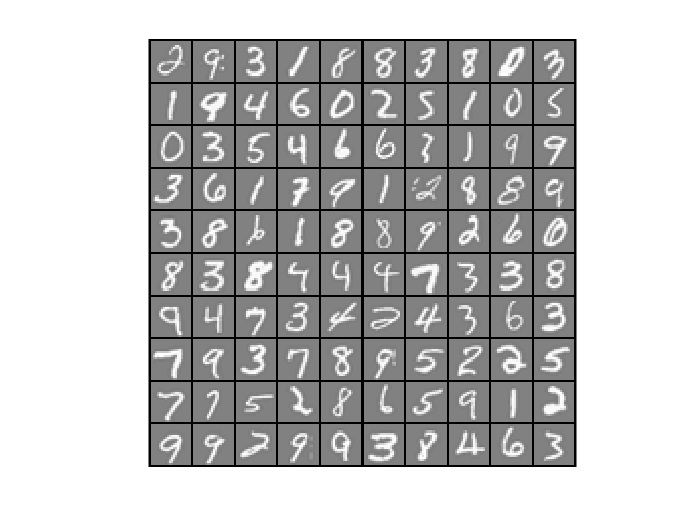

function [h, display_array] = displayData(X, example_width)
%DISPLAYDATA Display 2D data in a nice grid
%   [h, display_array] = DISPLAYDATA(X, example_width) displays 2D data
%   stored in X in a nice grid. It returns the figure handle h and the 
%   displayed array if requested.


% Set example_width automatically if not passed in

X =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0

if ~exist('example_width', 'var') || isempty(example_width) 
	example_width = round(sqrt(size(X, 2)));
end


Theta1 =    -0.0226   -0.0000    0.0000   -0.0000    0.0001   -0.0002   -0.0027    0.0015    0.0025    0.0007   -0.0006   -0.0002    0.0005    0.0011    0.0004    0.0004    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0007   -0.0004    0.0022    0.0093    0.0151    0.0074    0.0077    0.0006   -0.0087   -0.0137   -0.0018   -0.0020   -0.0013    0.0000    0.0036    0.0003   -0.0001   -0.0000    0.0000    0.0004   -0.0043   -0.0244   -0.0430   -0.0234    0.0488    0.1256
   -0.0984    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0005   -0.0010   -0.0010    0.0001    0.0026    0.0008   -0.0005   -0.0007    0.0008   -0.0000   -0.0002   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0002   -0.0015   -0.0030   -0.0142   -0.0494   -0.0224   -0.0224   -0.0034    0.0077    0.0080   -0.0161   -0.0053   -0.0010   -0.0042   -0.0062   -0.0010   -0.0001   -0.0000   -0.0000   -0.0001    0.0018    0.0461    0.1169    0.0233   -0.1162

Theta2 =    -0.7610   -1.2124   -0.1019   -2.3685   -1.0578   -2.2082    0.5638    1.2111    2.2103    0.4446   -1.1824    1.0429   -1.6056    1.3042    1.3718    1.7483   -0.2337   -1.5201    1.1532    0.1037   -0.3721   -0.6153   -0.1257   -2.2719   -0.7184   -1.2969
   -0.6179    0.6156   -1.2655    1.8575   -0.9185   -0.0550   -0.3859    1.2952   -1.5684   -0.9703   -2.1833   -2.8503   -2.0773    1.6316    0.3490    1.8279   -2.4417   -0.8563   -0.2983   -2.0795   -1.2933    0.8998    0.2831    2.3118   -2.4644    1.4566
   -0.6893   -1.9454    2.0136   -3.1232   -0.2362    1.3868    0.9098   -1.5477   -0.7983   -0.6560    0.7354   -2.5859    0.4721    0.5535    2.5126   -2.4167   -1.6390    1.2027   -1.2025   -1.8345   -1.8801   -0.3406    0.2369   -1.0614    1.0276   -0.4769
   -0.6783    0.4630    0.5849   -0.1650    1.9326   -0.2297   -1.8473    0.4901    1.0715   -3.3191    1.5411    0.3737   -0.8648   -2.5827    0.9706   -0.5102   -0.6843   -1.6471    0.2115   -0.2742    1.72

% Gray Image
colormap(gray);



Training Set Accuracy: 97.520000


% Compute rows, cols
[m n] = size(X);
example_height = (n / example_width);

% Compute number of items to display
display_rows = floor(sqrt(m));
display_cols = ceil(m / display_rows);

% Between images padding
pad = 1;

% Setup blank display
display_array = - ones(pad + display_rows * (example_height + pad), ...
                       pad + display_cols * (example_width + pad));

% Copy each example into a patch on the display array
curr_ex = 1;
for j = 1:display_rows
	for i = 1:display_cols
		if curr_ex > m, 
			break; 
		end
		% Copy the patch
		
		% Get the max value of the patch
		max_val = max(abs(X(curr_ex, :)));
		display_array(pad + (j - 1) * (example_height + pad) + (1:example_height), ...
		              pad + (i - 1) * (example_width + pad) + (1:example_width)) = ...
						reshape(X(curr_ex, :), example_height, example_width) / max_val;
		curr_ex = curr_ex + 1;
	end
	if curr_ex > m, 
		break; 
	end
end

% Display Image
h = imagesc(display_array, [-1 1]);

% Do not show axis
axis image off

drawnow;

end



$$J\left( \theta  \right)=\frac{1}{m}\sum\limits_{i=1}^{m}{[-{{y}^{(i)}}\log \left( {h_\theta}\left( {{x}^{(i)}} \right) \right)-\left( 1-{{y}^{(i)}} \right)\log \left( 1-{h_\theta}\left( {{x}^{(i)}} \right) \right)]}+\frac{\lambda }{2m}\sum\limits_{j=1}^{n}{\theta _{j}^{2}}\\
{\theta_0}:={\theta_0}-a\frac{1}{m}\sum\limits_{i=1}^{m}{(({h_\theta}({{x}^{(i)}})-{{y}^{(i)}})x_{0}^{(i)}})\\
{\theta_j}:={\theta_j}-a[\frac{1}{m}\sum\limits_{i=1}^{m}{({h_\theta}({{x}^{(i)}})-{{y}^{(i)}})x_{j}^{\left( i \right)}}+\frac{\lambda }{m}{\theta_j}]$$


function g = sigmoid(z)
    g = 1 ./ (1 + exp(-z));
end

% y 只有 0 或者 1
function [J, grad] = lrCostFunction(theta, X, y, lambda)
    % theta = [0, 0, 0 ... ]^T
    m = size(X, 1);
    h_theta = sigmoid(X * theta);
    %J    = zeros(m, 1); % 这里理解错误，应该是一个值
    J = 0;
    grad = zeros(m, 1);
    temp = [0; theta(2:end)];
    %J = sum(-y .* log(h_theta) - (1 - y) .* log(1 - h_theta), 1); 这么写完全是没有算过 shape
    J = sum(-y .* log(h_theta) - (1 - y) .* log(1 - h_theta)) / m ...
            + lambda * temp' * temp / (2 * m);
    
%     theta_without_first = zeros(length(theta), 1);
%     theta_without_first = theta(2:end, :);
    
    grad = X' * (h_theta - y) / m + lambda .* temp / m;
end

这个掌握的不是很好！注意如何设计 all_theta(num_labels * feature)，如何一次性训练每个分类的 theta

function [all_theta] = oneVsAll(X, y, num_labels, lambda)
%ONEVSALL trains multiple logistic regression classifiers and returns all
%the classifiers in a matrix all_theta, where the i-th row of all_theta 
%corresponds to the classifier for label i
%   [all_theta] = ONEVSALL(X, y, num_labels, lambda) trains num_labels
%   logistic regression classifiers and returns each of these classifiers
%   in a matrix all_theta, where the i-th row of all_theta corresponds 
%   to the classifier for label i
    % Some useful variables
    m = size(X, 1);
    n = size(X, 2);
    
    % You need to return the following variables correctly 
    all_theta = zeros(num_labels, n + 1);
    
    % Add ones to the X data matrix
    X = [ones(m, 1) X];
    
    
    options = optimset('GradObj', 'on', 'MaxIter', 50);
    initial_theta = zeros(n + 1, 1);
    
    % 每个类训练一遍
    for i = 1:num_labels
%         [theta, cost] = fmincg(@(t)(lrCostFunction(t, X, y == i, lambda)), initial_theta, options);
%         all_theta(i, :) = theta;
        all_theta(i, :) = fminunc (@(t)(lrCostFunction(t, X, (y == i), lambda)), ...
                    initial_theta, options);
    end
end


function p = predictOneVsAll(all_theta, X)
    %PREDICT Predict the label for a trained one-vs-all classifier. The labels 
    %are in the range 1..K, where K = size(all_theta, 1). 
    %  p = PREDICTONEVSALL(all_theta, X) will return a vector of predictions
    %  for each example in the matrix X. Note that X contains the examples in
    %  rows. all_theta is a matrix where the i-th row is a trained logistic
    %  regression theta vector for the i-th class. You should set p to a vector
    %  of values from 1..K (e.g., p = [1; 3; 1; 2] predicts classes 1, 3, 1, 2
    %  for 4 examples) 
    
    m          = size(X, 1);
%     num_labels = size(all_theta, 1);
    
    % You need to return the following variables correctly 
    p = zeros(size(X, 1), 1);
    
    % Add ones to the X data matrix
    X = [ones(m, 1) X];
    
    
%     [M, p] = max(X * all_theta', [], 2); 忘记sigmoid！！
    [M, p] = max(sigmoid(X * all_theta'), [], 2);
end

`theta 其尺寸为：以第 j + 1`� `层的激活单元数量为行数，以第 `j � `层的激活单元数加一为列数的矩阵`  

同时第二层的输入的形状是什么也要知道，我画了一个图，应该好理解。

sample * theta^T = 一个神经元(注意角度)

function p = predict(Theta1, Theta2, X)
    %PREDICT Predict the label of an input given a trained neural network
    %   p = PREDICT(Theta1, Theta2, X) outputs the predicted label of X given the
    %   trained weights of a neural network (Theta1, Theta2)
    
    % Useful values
    m = size(X, 1);
    num_labels = size(Theta2, 1);
    
    % You need to return the following variables correctly 
    p = zeros(size(X, 1), 1);
    
    % ====================== YOUR CODE HERE ======================
    % Instructions: Complete the following code to make predictions using
    %               your learned neural network. You should set p to a 
    %               vector containing labels between 1 to num_labels.
    %
    % Hint: The max function might come in useful. In particular, the max
    %       function can also return the index of the max element, for more
    %       information see 'help max'. If your examples are in rows, then, you
    %       can use max(A, [], 2) to obtain the max for each row.
    %
    
    % 1th
%     X       = [ones(m, 1) X];
%     a_sup_2 = sigmoid(Theta1 * X'); % 已经增加了一个 \theta 用于额外的 1。
%     a_sup_2 = [ones(1, size(a_sup_2, 2)); a_sup_2];
%     a_sup_3 = sigmoid(Theta2 * a_sup_2);
%     [M, p_t] = max(a_sup_3, [], 1);
%     p = p_t';
    % 2nd
    X       = [ones(m, 1) X];
    a_sup_2 = sigmoid(X * Theta1'); % a_sup_2 一行是 sample, sample * theta^T = 一个神经元
    a_sup_2 = [ones(size(a_sup_2, 1), 1) a_sup_2]; % 增加 one 列
    a_sup_3 = sigmoid(a_sup_2 * Theta2');
    [aa, p] = max(a_sup_3, [], 2);
end